# Electrode localization using FreeSurfer + iElectrodes

Written by Qian Chu

Max Planck - University of Toronto Centre

Contact: qian.chu@{mail.utoronto.ca, ae.mpg.de}

Version: 250731

FreeSurfer version tested: 7.4.1

iElectrodes version tested: 1.020

## Checklist

Make sure that you have:

- Acquired the pre-op T1-weighted MRI scan (hereafter referred to as T1), the post-op CT scan (hereafter referred to as CT), and *optionally, the pre-op T2-weighted MRI scan (hereafter referred to as T2)*. The scans should be in DICOM (.dcm) or NIFTI (.nii) format.

- Make sure that .dcm files in one folder all belong to the same scan (i.e., create dedicated T1/T2/CT folders when preparing DICOM files)

- FreeSurfer installed on this computer. FreeSurfer can be installed on Linux or MacOS. Download instructions: [https://surfer.nmr.mgh.harvard.edu/fswiki/rel7downloads](https://surfer.nmr.mgh.harvard.edu/fswiki/rel7downloads)

- Downloaded iElectrodes from [https://sourceforge.net/projects/ielectrodes/files/latest/download](https://sourceforge.net/projects/ielectrodes/files/latest/download) and put the unzipped package in this elec_loc folder.

## Run sections below one by one

## Setup

clearvars, clc, close all

Specify paths:

- To FreeSurfer home directory ($FREESURFER_HOME)

cfg.dir_fs = '/home/qian/research/freesurfer';

- To FreeSurfer subject directory ($SUBJECTS_DIR)

cfg.dir_fs_subjects = '/home/qian/research/fs_subjects';

FREESURFER_HOME and SUBJECTS_DIR can be found in the command line outputs when you source FreeSurfer using *SetUpFreeSurfer.sh*

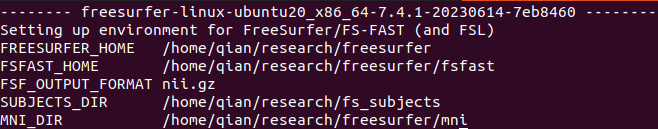

Type patient ID below:

pat.id  = "TWH240";

Set up paths:

elec_loc_path       = matlab.desktop.editor.getActiveFilename;
elec_loc_path_parts = split(elec_loc_path, filesep);
cfg.dir_el          = strjoin(elec_loc_path_parts(1:end-1), filesep);
addpath(fullfile(cfg.dir_el, 'functions'))
[cfg, pat] = el_init(cfg, pat);

## Import and preprocess scans

Say goodbye to manual preprocessing and coregistration of anatomical scans! The script here imports the T1, CT (and optionally T2) scans into a FreeSurfer subject folder. Moreover, it performs automatic AC-PC alignment, coregistration, and defacing. The resulting scans are ready for electrode localization and data sharing.

### Procedure

- Run this section.

- ([UI prompt] [If preprocessed files already exist in the output folder] Indicate whether you want to re-import and re-preprocess the scans. If you choose no, the section will simply read and print the paths to preprocessed scans

- [UI prompt] Indicate whether you want to import DICOM or NIFTI files.

- [UI file/directory selection] Select T1, CT (and T2) one by one according to prompt in the dialog title. For DICOM, you need to select a folder containing all .dcm files corresponding to one scan. For NIFTI, you need to select a single .nii file.

- Wait for processing. During CT processing, a viewer window will pop up to let you inspect the CT scan. You can adjust the minimum value to roughly determine an intensity threshold such that only bones and electrodes are visible to effectively de-identify the patient. Enter the value into the textbox.

- A viewer window will pop up at the end to allow you to inspect the scans overlaid on top of grayscale T1. The scans should be aligned to each other and defaced. Close the window when done inspecting.

### Output

- The elec_loc subfolder (`pat.dir.el`) in FreeSurfer subject folder with preprocessed (AC-PC aligned, defaced, and co-registered) scans. Scan file names comply with BIDS format (e.g., *sub-XXX_acq-preop_T1w.nii*). Compressed scans (.nii.gz) are further available in elec_loc/BIDS_outputs/anat.

- Updated `pat` structure.

TWH240 preprocessed scans not found. Importing...
Validating 160 files ... (160 valid)
Converting 1 series (Siemens) into 4-D .nii: subject 'TWH240'
 x2_25_133365539550909391831518963045950637128             320x320x160x1
Elapsed time by dicm2nii is 2.4 seconds

Validating 181 files ... (181 valid)
Converting 1 series (Canon) into 4-D .nii: subject 'TWH240'
 x2_25_248508444017636456709955402754597619350             512x512x181x1
Elapsed time by dicm2nii is 5.2 seconds

Validating 30 files ... (30 valid)
Converting 1 series (Siemens) into 4-D .nii: subject 'TWH240'
 x2_25_314265792799022494241264658986868160322             480x480x30x1
Elapsed time by dicm2nii is 0.8 seconds

**********PROCESSING T1**********

>> el_center
	INPUT: /home/qian/Desktop/Patient DICOMs/TWH240/T1/x2_25_133365539550909391831518963045950637128.nii
	OUTPUT: /home/qian/research/fs_subjects/TWH240/elec_loc/sub-TWH240_acq-preop_T1w.nii
Done
>> el_coreg
	REFERENCE: /home/qian/Documents/GitHub/elec_loc/icbm_avg_152_t

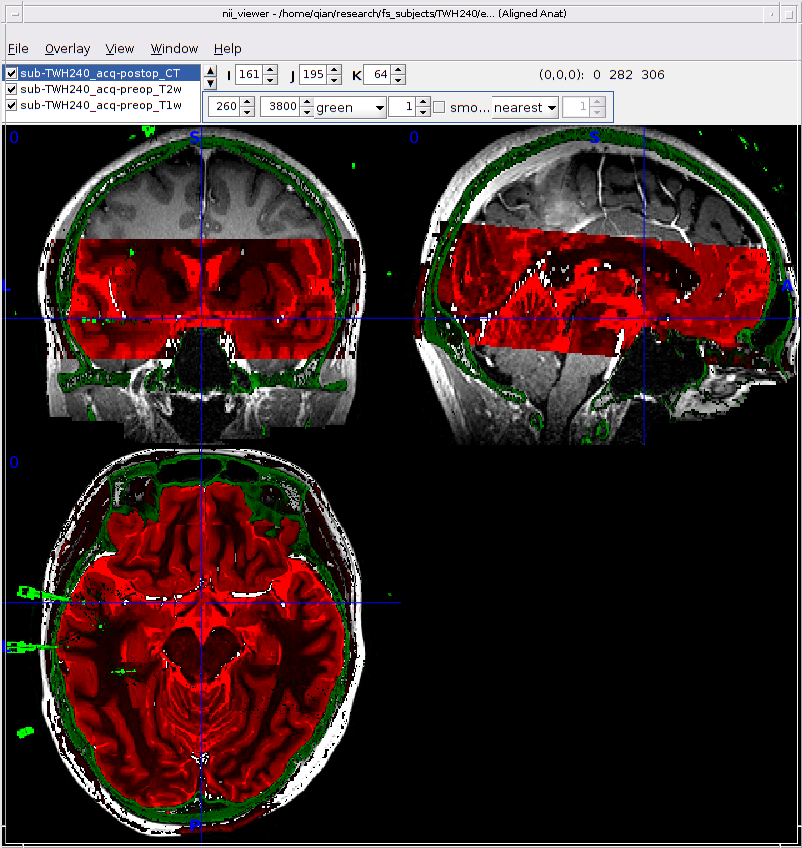

pat = el_import_scans(pat, cfg);

## Electrode labeling using iElectrodes

In this pipeline we use [iElectrodes](https://sourceforge.net/p/ielectrodes/wiki/Home/), an easy-to-use and robust toolbox for localizing intracranial electrodes. The code in this section launches iElectrodes.    

Welcome to iElectrodes.
iElectrodes toolbox is FOR RESEARCH PURPOSES ONLY. This software is
for research purposes only and has NOT BEEN APPROVED FOR CLINICAL USE.
Help about using iElectrodes can be found online in 
https://sourceforge.net/p/ielectrodes/wiki/Home/
You have the last version of iElectrodes :-)
Project estructure is beeing checked...
Checking done.


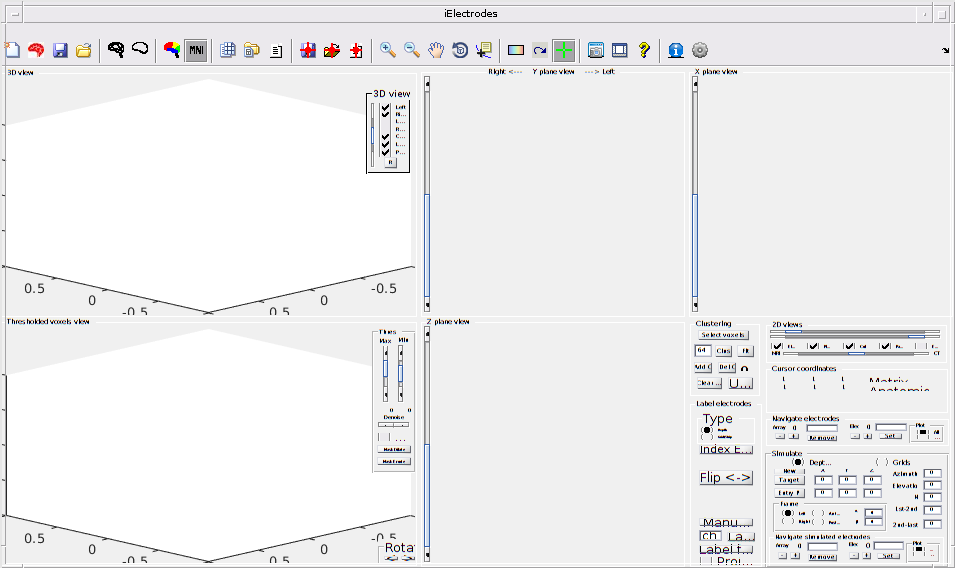

cd(pat.dir.el)
electrodes_gui

### iElectrodes toolbars

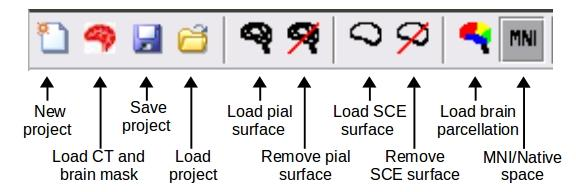

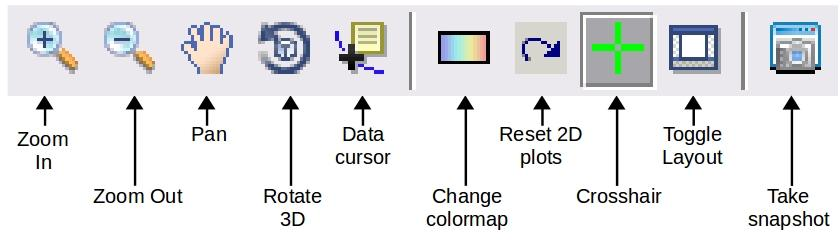

### Steps

- Click "New project" (see icon above) and load *sub-XXX_T1w.nii.* T1 scan will appear on the top right corner of the iElectrodes window once loading is complete

- Click "Load CT and brain mask" (see icon above). You will be prompted to select the CT scan *sub-XXX_CT.nii.*. After a while, you will be prompted again to select the brain mask. You can load the co-registered CT again. Using other masks like ribbon.nii might make it hard to visualize other landmarks like bolts, which are sometimes useful when navigating electrode locations.

- Follow [this tutorial](https://sourceforge.net/p/ielectrodes/wiki/Localization%20and%20labeling%20of%20intracranial%20electrodes/) to threshold CT, select above-threshold voxels, cluster and label electrodes.

- When you are done, save the project (see icon above) and name it as *sub-XXX.iel*. You can also save the project halfway and reload it using the "Load project" button.

## FreeSurfer recon-all with optional subregion segmentation

[https://surfer.nmr.mgh.harvard.edu/fswiki/recon-all](https://surfer.nmr.mgh.harvard.edu/fswiki/recon-all)

`recon-all` is a command line script in FreeSurfer. The name comes from "reconstruction of all structures," and this command calls a series of scripts for preprocessing, segmentation, and cortical surface reconstruction.

Subsequently, users can also choose to perform subregion segmentation, including the [hippocampus/amygdala](https://surfer.nmr.mgh.harvard.edu/fswiki/HippocampalSubfieldsAndNucleiOfAmygdala) and [thalamus](https://surfer.nmr.mgh.harvard.edu/fswiki/ThalamicNuclei).

### Inputs

- [Auto-loaded] Defaced, AC-PC aligned T1 (and T2)

- [Select from dropdown box] whether to perform hippocampus/amygdala and/or thalamus subregion segmentation.

### Outputs

- FreeSurfer subject folder *$SUBJECTS_DIR/PATIENT_NAME*

After executing, wait a few minutes to make sure recon-all initiates without errors. The execution takes **10 hours or more **so it might be a good idea to run it overnight. Lay down .... ;)

segment_amygdala_hippocampus = true;
segment_thelamus = false;
el_fs_recon_all(cfg, pat, segment_amygdala_hippocampus, segment_thelamus)

mri_convert /home/qian/research/fs_subjects/TWH240/elec_loc/sub-TWH240_acq-preop_T1w.nii /home/qian/research/fs_subjects/TWH240/mri/orig/001.mgz 
reading from /home/qian/research/fs_subjects/TWH240/elec_loc/sub-TWH240_acq-preop_T1w.nii...
TR=2200.00, TE=0.00, TI=0.00, flip angle=0.00
i_ras = (-0.999029, -0.0437765, -0.00495338)
j_ras = (-0.0433813, 0.997095, -0.0626139)
k_ras = (-0.00768209, 0.062335, 0.998026)
writing to /home/qian/research/fs_subjects/TWH240/mri/orig/001.mgz...
fs-check-version --s TWH240 --o /tmp/tmp.lFxaH8
Tue Sep  9 16:32:47 EDT 2025

setenv SUBJECTS_DIR /home/qian/research/fs_subjects
cd /home/qian/research/fs_subjects/TWH240/elec_loc
/home/qian/research/freesurfer/bin/fs-check-version --s TWH240 --o /tmp/tmp.lFxaH8
-rwxrwxr-x 1 qian qian 18565 Jun 14  2023 /home/qian/research/freesurfer/bin/fs-check-version

freesurfer-linux-ubuntu20_x86_64-7.4.1-20230614-7eb8460
$Id$
Linux N2B-KDT 5.15.0-139-generic #149~20.04.1-Ubuntu SMP Wed Apr 16 08:29:56 UTC 2025 x86_64 x8

## Convert .mgz to .nii and create bilateral meshes

Some FreeSurfer .mgz output files are used by iElectrodes, yet iElectrodes only recognizes NIFTI (.nii). The function below does a stacked conversion.

### Inputs

- [Auto-loaded] .mgz files in FreeSurfer *mri* subfolder

- [Auto-loaded] xh.white and xh.pial.T1 files in FreeSurfer *surf* subfolder

### Outputs

- .nii files in FreeSurfer *mri* subfolder

- bil_white.nv and bil_pial.nv in *elec_loc* subfolder

el_mgz2nii(cfg, pat)

mri_convert -it mgz -ot nii --out_orientation RAS /home/qian/research/fs_subjects/TWH240/mri/aparc.DKTatlas+aseg.mgz /home/qian/research/fs_subjects/TWH240/mri/aparc.DKTatlas+aseg.nii 
reading from /home/qian/research/fs_subjects/TWH240/mri/aparc.DKTatlas+aseg.mgz...
TR=2200.00, TE=0.00, TI=0.00, flip angle=0.00
i_ras = (-1, -3.95812e-09, 4.65661e-10)
j_ras = (0, 0, -1)
k_ras = (-1.36788e-09, 1, -7.45058e-09)
Setting output orientation to RAS
Reslicing using trilinear interpolation 
writing to /home/qian/research/fs_subjects/TWH240/mri/aparc.DKTatlas+aseg.nii...
mri_convert -it mgz -ot nii --out_orientation RAS /home/qian/research/fs_subjects/TWH240/mri/aparc.a2009s+aseg.mgz /home/qian/research/fs_subjects/TWH240/mri/aparc.a2009s+aseg.nii 
reading from /home/qian/research/fs_subjects/TWH240/mri/aparc.a2009s+aseg.mgz...
TR=2200.00, TE=0.00, TI=0.00, flip angle=0.00
i_ras = (-1, -3.95812e-09, 4.65661e-10)
j_ras = (0, 0, -1)
k_ras = (-1.36788e-09, 1, -7.45058e-09)
Setting output orientati

el_merge_mesh(pat)

Merged mesh successfully saved at
	/home/qian/research/fs_subjects/TWH240/elec_loc/bil_white.nv
Merged mesh successfully saved at
	/home/qian/research/fs_subjects/TWH240/elec_loc/bil_pial.nv


## Read localization results from .iel

### Input

- [Select from GUI] iElectrodes project .iel file

### Output

- Updated `pat` structure with new field `elec`

pat = el_get_elec(pat);

Electrode group: LAINS
	LAINS1 | LAINS2 | LAINS3 | LAINS4 | LAINS5 | LAINS6 | LAINS7 | LAINS8
Electrode group: LMINS
	LMINS1 | LMINS2 | LMINS3 | LMINS4 | LMINS5 | LMINS6 | LMINS7 | LMINS8
Electrode group: LPINS
	LPINS1 | LPINS2 | LPINS3 | LPINS4 | LPINS5 | LPINS6 | LPINS7 | LPINS8
Electrode group: LAMYG
	LAMYG1 | LAMYG2 | LAMYG3 | LAMYG4 | LAMYG5 | LAMYG6 | LAMYG7 | LAMYG8
Electrode group: LSTGant
	LSTGant1 | LSTGant2 | LSTGant3 | LSTGant4 | LSTGant5 | LSTGant6 | LSTGant7 | LSTGant8
Electrode group: LAHC
	LAHC1 | LAHC2 | LAHC3 | LAHC4 | LAHC5 | LAHC6 | LAHC7 | LAHC8
Electrode group: LPHG
	LPHG1 | LPHG2 | LPHG3 | LPHG4 | LPHG5 | LPHG6 | LPHG7 | LPHG8
Electrode group: LSTGpost
	LSTGpost1 | LSTGpost2 | LSTGpost3 | LSTGpost4 | LSTGpost5 | LSTGpost6 | LSTGpost7 | LSTGpost8
Electrode group: LPHC
	LPHC1 | LPHC2 | LPHC3 | LPHC4 | LPHC5 | LPHC6 | LPHC7 | LPHC8
Electrode group: LMOTOR
	LMOTOR1 | LMOTOR2 | LMOTOR3 | LMOTOR4 | LMOTOR5 | LMOTOR6 | LMOTOR7 | LMOTOR8
Electrode group: LMEG
	LMEG1 | LM

## [If using Behke-Fried depth electrodes] Estimate microwire location

iElectrodes cannot properly recognize microwires (which may or may not be visible on a post-op CT). A workaround is to estimate their location using locations of the 1st and 2nd electrodes (deepest two) and the distance between the first electrode and the microwire bundle.

### Input

- [Auto-loaded] MATLAB structure `elec`

- [Type in field below] Known distance from the microwire bundle to the deepest macro contact (specify in code below)

### Output

- Updated MATLAB structure `elec` with microwires

% Specify distance from the microwire bundle to the deepest macro contact
% (in mm)
micro_to_macro_dist = 3;
pat.elec = el_est_micro(pat.elec, micro_to_macro_dist);

Every bundle has microwire specified. No further operation.


## [If re-referencing with bipolar setup] Estimate virtual electrode location

Estimate the middle point between adjacent contacts for each depth electrode and add it to the electrodes structure with type `bipolar`

### **Input**

- [Auto-loaded] MATLAB structure `elec`

### **Output**

- Updated MATLAB structure `elec` with virtual electrodes

pat.elec = el_bipolar(pat.elec);

Estimated location for depth electrode 	LAINS
Estimated location for depth electrode 	LMINS
Estimated location for depth electrode 	LPINS
Estimated location for depth electrode 	LAMYG
Estimated location for depth electrode 	LSTGant
Estimated location for depth electrode 	LAHC
Estimated location for depth electrode 	LPHG
Estimated location for depth electrode 	LSTGpost
Estimated location for depth electrode 	LPHC
Estimated location for depth electrode 	LMOTOR
Estimated location for depth electrode 	LMEG
Estimated location for depth electrode 	LSENS


## Visualize electrode locations on native T1 and CT

### Output

- Figures for each channel in the subfolder *elec_loc/slice_views*

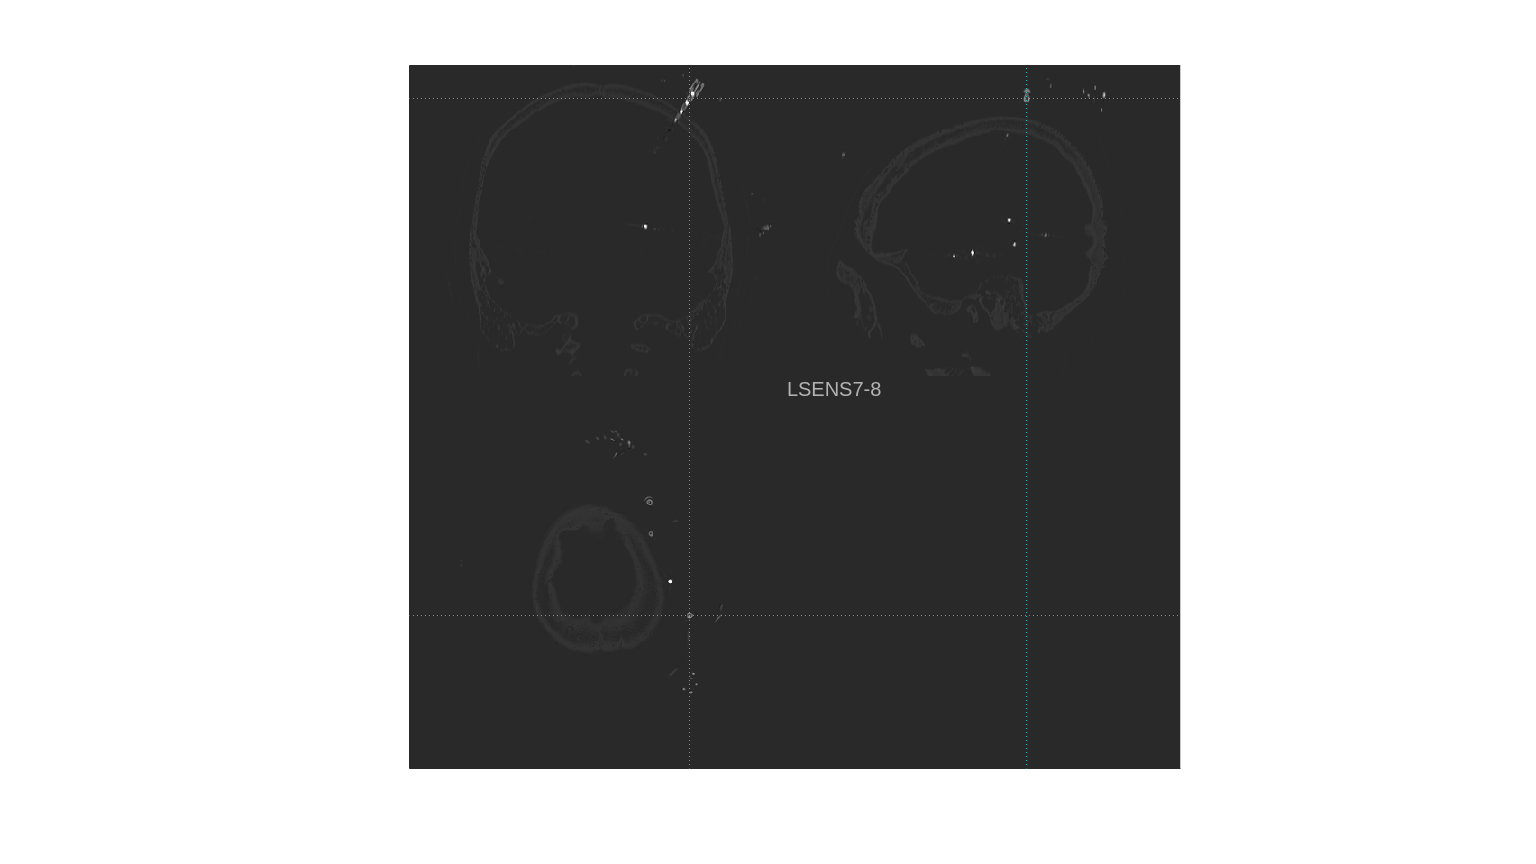

el_slice_view(pat)

## Get FreeSurfer labels in the native space

The main purpose of running FreeSurfer recon-all is to produce automated cortical parcellation. By combining electrode location with the parcellations, we can automatically assign them anatomical labels. For details of the parcellations see [https://surfer.nmr.mgh.harvard.edu/fswiki/CorticalParcellation.](https://surfer.nmr.mgh.harvard.edu/fswiki/CorticalParcellation.)

The output filenames are BIDS-compliant ([https://bids-specification.readthedocs.io/en/stable/modality-specific-files/intracranial-electroencephalography.html#channels-description-_channelstsv](https://bids-specification.readthedocs.io/en/stable/modality-specific-files/intracranial-electroencephalography.html#channels-description-_channelstsv)). Since results from this section are derived from the patient's native space (which is ACPC aligned), the identifier is `sub-xxx_space-ACPC_electrodes`.

### Input

- [Auto-loaded] MATLAB structure `elec`

- [Auto-loaded] FreeSurfer parcellation files 

### Output

- BIDS-formatted electrode location files (in .tsv and .csv)

- BrainNet Viewer node file

- BrainNet Viewer glass brain

### To do:

- Get FreeSurfer label with iElectrodes' `anatomicLabelFS` function

- Expand to also get hippocampal subfield labels

el_elec_native(cfg, pat, segment_amygdala_hippocampus, segment_thelamus)

Getting labels from atlas aparc.a2009s+aseg
Getting labels from atlas aparc.DKTatlas+aseg
Getting labels from atlas wmparc
Getting labels from atlas lh.hippoAmygLabels-T1.v22
Getting labels from atlas rh.hippoAmygLabels-T1.v22
Getting labels from atlas lh.hippoAmygLabels-T1-T2.v22


Getting labels from atlas rh.hippoAmygLabels-T1-T2.v22
Please cite:
Xia M, Wang J, He Y (2013) BrainNet Viewer: A Network Visualization Tool for Human Brain Connectomics. PLoS ONE 8: e68910.
An example:
'The brain networks were visualized with the BrainNet Viewer (http://www.nitrc.org/projects/bnv/) (Xia et al., 2013)'.
Electrode location (native ACPC space) saved:
	 CSV:           /home/qian/research/fs_subjects/TWH240/elec_loc/sub-TWH240_space-ACPC_electrodes.csv
	 TSV:           /home/qian/research/fs_subjects/TWH240/elec_loc/BIDS_outputs/ieeg/sub-TWH240_space-ACPC_electrodes.tsv
	 BrainNet node: /home/qian/research/fs_subjects/TWH240/elec_loc/sub-TWH240_space-ACPC_electrodes.node
	 Glass brain:   /home/qian/research/fs_subjects/TWH240/elec_loc/BIDS_outputs/ieeg/sub-TWH240_acq-ACPCRender_photo.jpg


## Get electrode coordinates in MNI152 space

For group-level visualization of electrode location, mapping locations from native to standardized spaces is necessary. This section does a linear transform to electrode locations to map them to the MNI152 (ICBM152) space.

[https://www.bic.mni.mcgill.ca/ServicesAtlases/ICBM152Lin](https://www.bic.mni.mcgill.ca/ServicesAtlases/ICBM152Lin)

### Input

- [Auto-loaded] MATLAB structure `elec`

- [Auto-loaded] T1 scan to be registered to MNI152Lin template

### Output

- BIDS-formatted electrode location files (in .tsv and .csv)

- BrainNet Viewer node file

- BrainNet Viewer glass brain

### To do:

- Get Harvard-Oxford atlas labels with iElectrodes' `anatomicLabel` function

- Get other labels for the MNI space (e.g. AAL)

el_elec_mni152(cfg, pat)

Please cite:
Xia M, Wang J, He Y (2013) BrainNet Viewer: A Network Visualization Tool for Human Brain Connectomics. PLoS ONE 8: e68910.
An example:
'The brain networks were visualized with the BrainNet Viewer (http://www.nitrc.org/projects/bnv/) (Xia et al., 2013)'.


Electrode location (MNI152 space) saved:
	 CSV:           /home/qian/research/fs_subjects/TWH240/elec_loc/sub-TWH240_space-MNI152Lin_electrodes.csv
	 TSV:           /home/qian/research/fs_subjects/TWH240/elec_loc/BIDS_outputs/ieeg/sub-TWH240_space-MNI152Lin_electrodes.tsv
	 BrainNet node: /home/qian/research/fs_subjects/TWH240/elec_loc/sub-TWH240_space-MNI152Lin_electrodes.node
	 Glass brain:   /home/qian/research/fs_subjects/TWH240/elec_loc/BIDS_outputs/ieeg/sub-TWH240_acq-MNI152Render_photo.jpg
